# MEG-MRI Coregistration

This tutorial guides you through the process of performing MEG-MRI Coregistation for source analysis. If you do not have the structural MRI of your participant, you can opt to use MEMES (MRI Estimation for MEG Sourcespace)

If you use MEMES or any of the scripts in the MEMES Github repository, we ask you to please cite the DOI link below:

Robert Seymour. (2018, October 8). 
Macquarie-MEG-Research/MEMES: For Zenodo (Version v0.31). 
Zenodo. 
http://doi.org/10.5281/zenodo.1451031

## Set-up Paths

The first step will be set up the paths on your machine. 

You will need to following toolboxes, which can be downloaded from Github 

- [Fieldtrip Toolbox](http://www.fieldtriptoolbox.org/)

- [MQ_MEG_Scripts](https://github.com/Macquarie-MEG-Research/MQ_MEG_Scripts)

- [MEMES](https://github.com/Macquarie-MEG-Research/MEMES)

%% Add Relevent Paths

% Path to the Fieldtrip Toolbox
path_to_fieldtrip       = '/Users/rseymoue/Documents/GitHub/fieldtrip';
 
% Path to MQ_MEG_Scripts
path_to_MQ_MEG_Scripts  = '/Users/rseymoue/Documents/GitHub/MQ_MEG_Scripts/';

% Path to MEMES
path_to_MEMES           = '/Users/rseymoue/Documents/GitHub/MEMES/';

% Path to the MRI library used for MEMES (adult)
path_to_MRI_library     = '/Volumes/Robert T5/new_HCP_library_for_MEMES/';

% Path to the structural MRI;
path_to_MRI             = '/Users/rseymoue/Documents/test_RS/RS.nii';

% Add Fieldtrip
addpath(path_to_fieldtrip);
ft_defaults;

% Add MQ_MEG_Scripts
addpath(genpath(path_to_MQ_MEG_Scripts));

% Add MEMES & Specify 
addpath(genpath(path_to_MEMES));


## Headshape Data Acquired with Polhemus --> Subject's Structural MRI

Here we opt to downsample the participants' facial information and use the option:

`cfg.facial_info_below_z     = 20;`

when calling `ft_downsample_headshape`. This will remove points 20mm below the nasion on the z-axis (up-down).

**NOTE:** These values may need to be adjusted based on your specific headshape data.

%% Polhemus with Subject's Structural MRI
% Load grad_trans.mat (output from mq_realign_sens)
load('grad_trans.mat');

% Downsample headshape
cfg                         = [];
cfg.downsample_facial_info  = 'yes';
cfg.facial_info_below_z     = 20;
hsp                         = downsample_headshape_new(cfg,...
    '0000_RS_polhemusVSiPad_2018_12_18.hsp');

% Perform coreg
mq_coreg(cd,grad_trans,path_to_MRI,0.05,hsp,0.1,8)
clear hsp

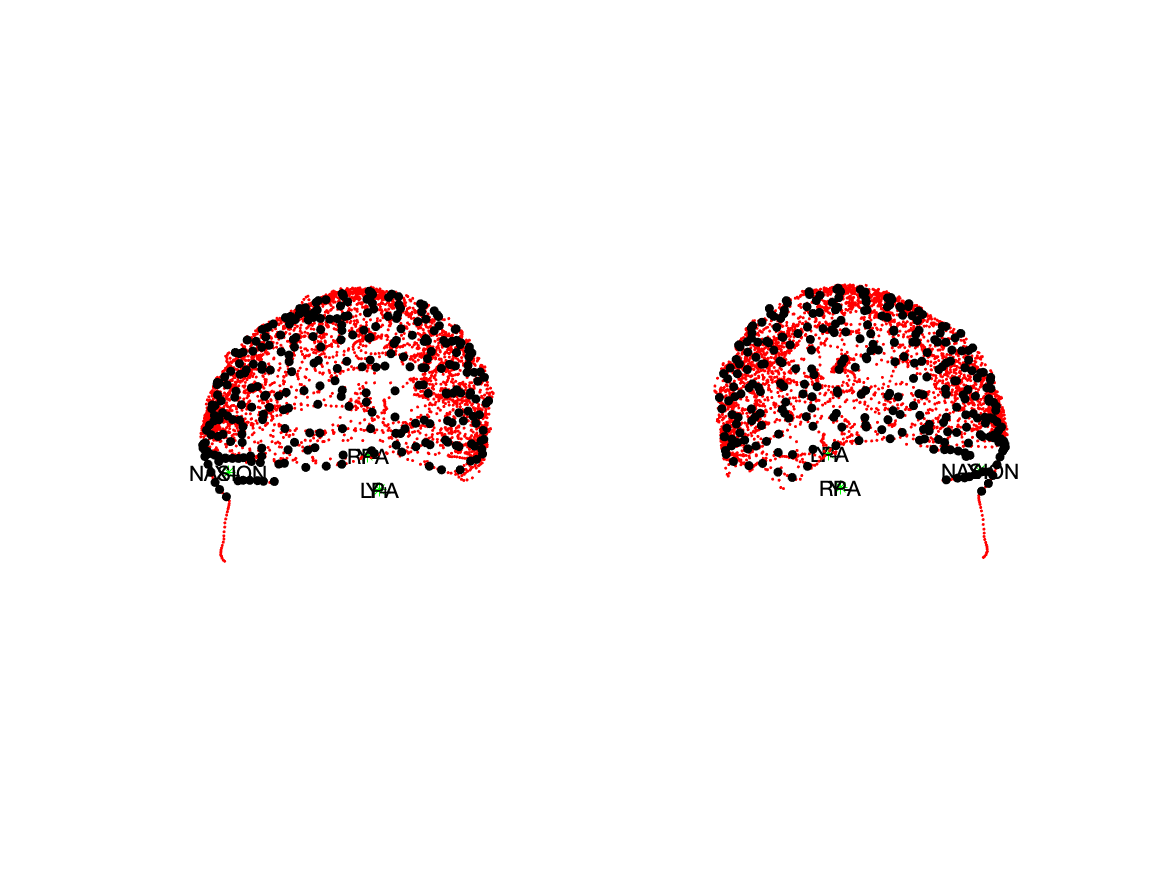

*Figure to assess the quality of the downsampled headshape*

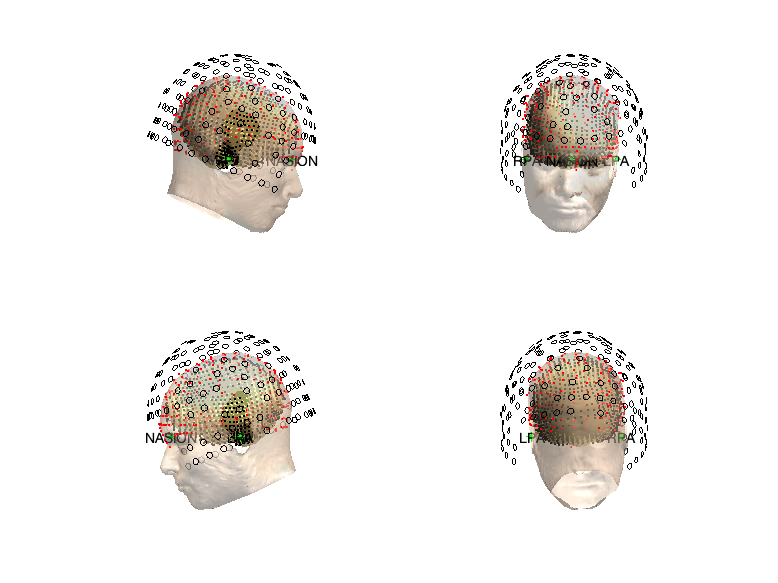

*Final coregistration, with sensors, headshape, mesh, headmodel and sourcemodel all plotted*

## Headshape Data Acquired with Polhemus --> MEMES

 Here we opt to downsample the participants' facial information and use the options:

`cfg.facial_info_below_x     = 60;`

`cfg.facial_info_below_z     = 20;`

when calling ft_downsample_headshape. This will remove points 20mm below the nasion on the z-axis (up-down); and 60mm on the y-axis (left-right).

**NOTE:** These values may need to be adjusted based on your specific headshape data.

%% Polhemus with MEMES
% Load grad_trans.mat (output from mq_realign_sens)
load('grad_trans.mat');

% Downsample headshape
cfg                         = [];
cfg.downsample_facial_info  = 'yes';
cfg.facial_info_below_x     = 60;
cfg.facial_info_below_z     = 20;
hsp                         = downsample_headshape_new(cfg,...
    '0000_RS_polhemusVSiPad_2018_12_18.hsp');

% MEMES
MEMES3(cd,grad_trans,hsp,path_to_MRI_library,'average',1,8,3);

clear hsp


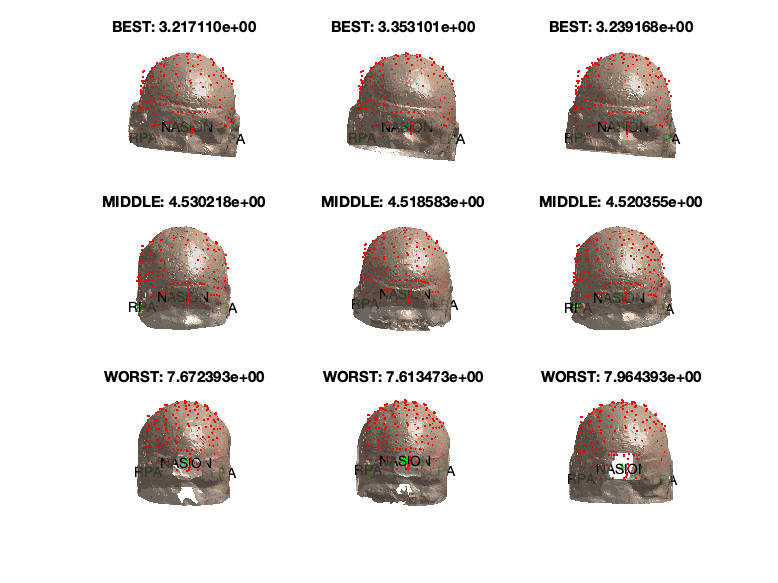

*Examples of the worst, middle & best fitting structural MRIs from the database*

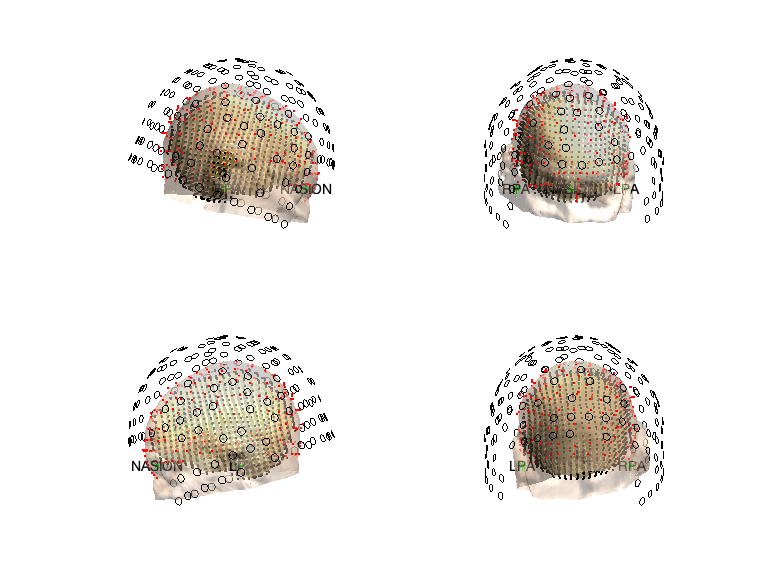

*Final coregistration, with sensors, headshape, mesh, headmodel and sourcemodel all plotted*

## Headshape Data Acquired with Structure Sensor --> Subject's Structural MRI

In this case, we do not need to downsample the headshape. The `mq_coreg_ipad` function extracts facial information from the `.hsp `file and MRI file and uses ICP to match these. Coregistration is therefore NOT based on the scalp surface.

%% Structure Sensor with Subject's Structural MRI
% Load headshape (no downsampling)
hsp     = ft_read_headshape('0000_XX_MEXX_2019_11_27.hsp.hsp');
hsp     = ft_convert_units(hsp,'mm');

% Perform Coreg
mq_coreg_ipad(cd,'RS.nii',0.05,hsp,8);

clear hsp

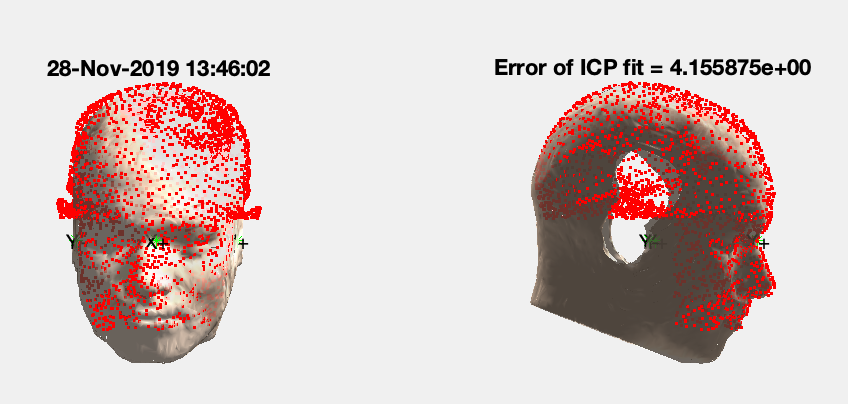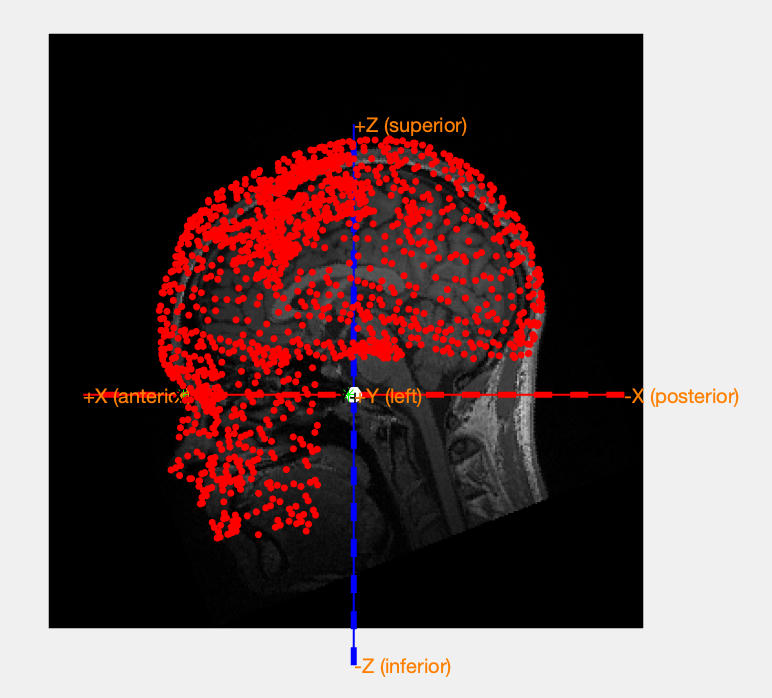

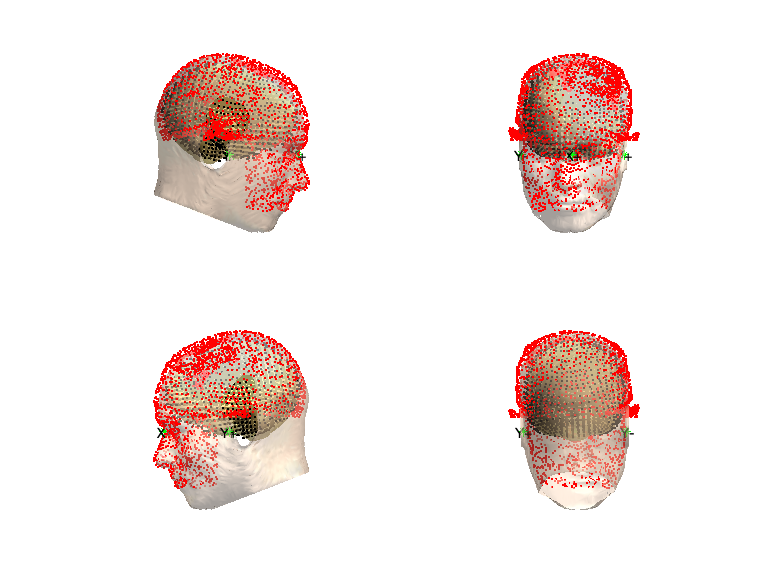

*Final coregistration, with headshape, mesh, headmodel and sourcemodel all plotted*

## Headshape Data Acquired with Structure Sensor --> MEMES

When dealing with headshape data acquired from the Structure Sensor, the `.hsp` file contains facial information which will not overlap with the MRI database. For this reason we need to remove these points, using the options:

`cfg.facial_info_below_x     = 60;`

`cfg.facial_info_below_z     = 20;`

when calling ft_downsample_headshape. This will remove points 20mm below the nasion on the z-axis (up-down); and 60mm on the y-axis (left-right).

**NOTE:** These values may need to be adjusted based on your specific headshape data.

%% Structure Sensor with MEMES
% Load grad_trans.mat (output from mq_realign_sens)
load('grad_trans.mat');

% Downsample Headshape
cfg                         = [];
cfg.downsample_facial_info  = 'yes';
cfg.facial_info_below_x     = 60;
cfg.facial_info_below_z     = 20;
hsp                         = downsample_headshape_new(cfg,...
    '0000_XX_MEXX_2019_11_27.hsp.hsp');

% MEMES
MEMES3(cd,grad_trans,hsp,path_to_MRI_library,'average',1,8,3);


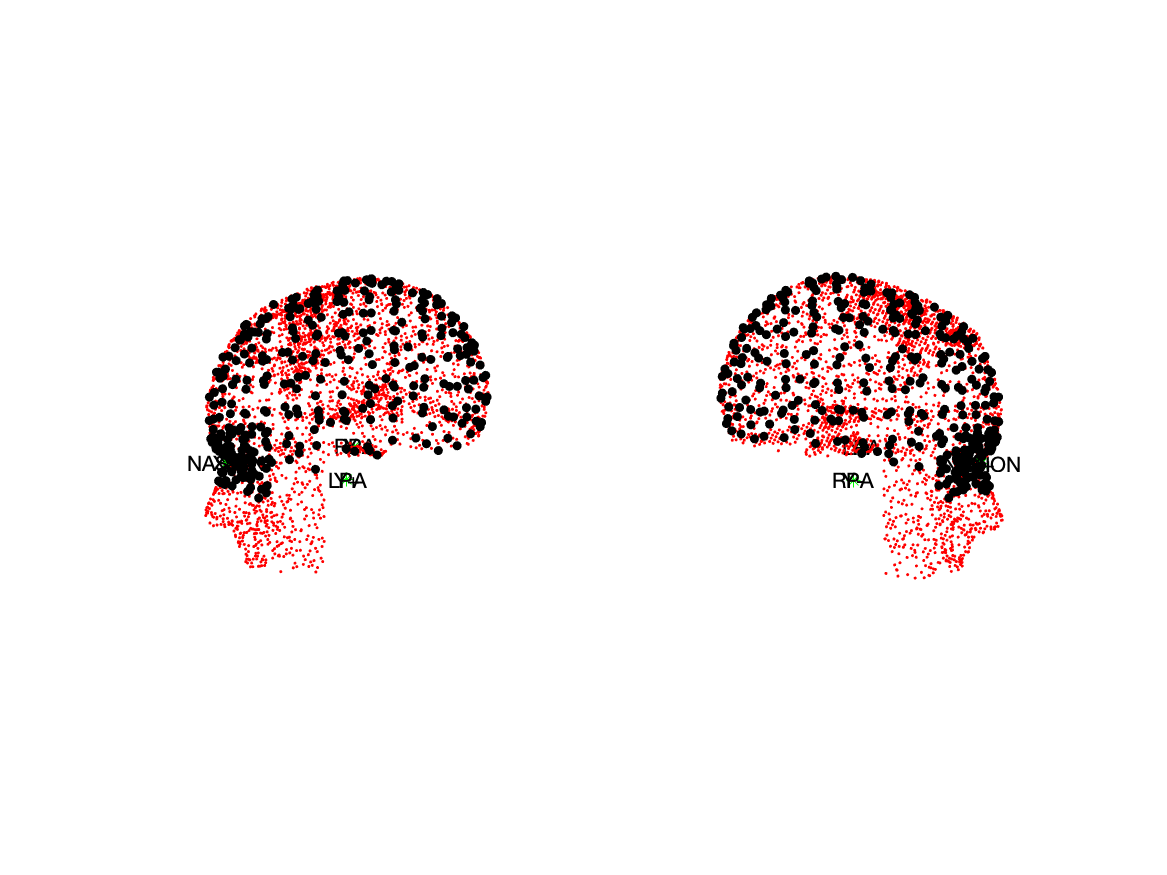

*Figure to assess the quality of the downsampled headshape*

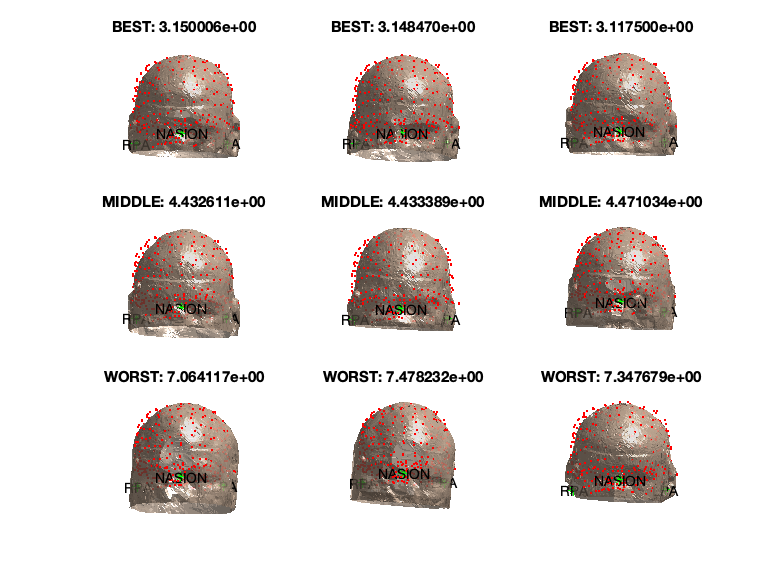

*Examples of the worst, middle & best fitting structural MRIs from the database*

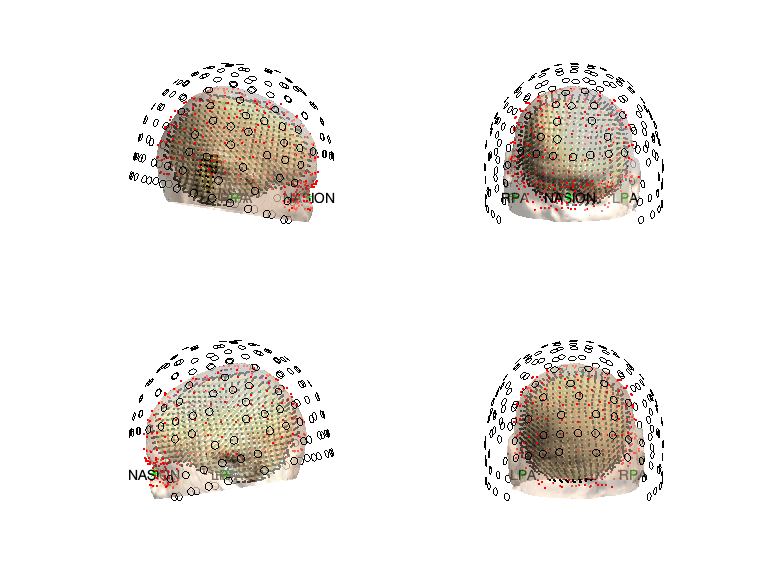

*Final coregistration, with sensors, headshape, mesh, headmodel and sourcemodel all plotted*